%clear all
%clc

J_b = 4.32e-5;
r = 0.02;
m = 0.27;
g = 9.81;
J_w = 14.025e-2;
K = 1e-3;
l = 0.49;
b = 1;

tspan = [0 10];
[t_spann, x_] = ode45(@(t, x) odefcn(t, x, 0.1), tspan, [0; 0; 0; 0]);

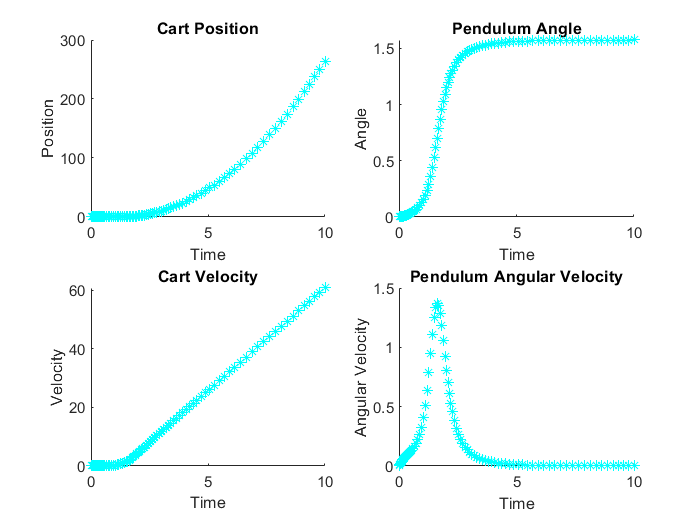

% Extracting the variables from the solution
cart_position = x_(:, 1);
cart_velocity = x_(:, 2);
pendulum_angle = x_(:, 3);
pendulum_angular_velocity = x_(:, 4);

% Plotting the results
figure;

subplot(2, 2, 1);
hold on
plot(t_spann, cart_position,'c*');
%plot(out.tout,out.x_simulation(:,2));
hold off
title('Cart Position');
xlabel('Time');
ylabel('Position');

subplot(2, 2, 2);
hold on
plot(t_spann, pendulum_angle,'c*');
%plot(out.tout, out.theta_simulation(:,2));
hold off
title('Pendulum Angle');
xlabel('Time');
ylabel('Angle');

subplot(2, 2, 3);
hold on
plot(t_spann, cart_velocity,'c*');
%plot(out.tout, out.x_dot_simulation(:,2));
hold off

title('Cart Velocity');
xlabel('Time');
ylabel('Velocity');

subplot(2, 2, 4);
hold on

plot(t_spann, pendulum_angular_velocity,'c*');
%plot(out.tout, out.theta_dot_simulation(:,2));
hold off
title('Pendulum Angular Velocity');
xlabel('Time');
ylabel('Angular Velocity');


% subtitle('Inverted Pendulum on a Cart Simulation Results');

## Q2

% Define symbolic variables
syms x1 x2 x3 x4 u real


% Equilibrium point
xeq = [0; 0; 0; 0];
ueq = 0;
A11 = (J_b/r^2+m);
A12 = ((m*r^2 +J_b)/r);
A21 =A12;
A22 =(m*x1^2+J_w+J_b);
B11 = (m*g*sin(x3));
B12 = (m*x1*x4^2);
B21 =(l*cos(x3)*u);
B22= (m*g*x1*cos(x3));
B23 =(K*l^2*x3*(-1));
B24 =(-(2*m*x1*x2+b*l^2)*x4);
C1= ((m*g*sin(x3)) +(m*x1*x4^2));
C2 =((l*cos(x3)*u) +(m*g*x1*cos(x3)) +(K*l^2*x3*(-1)) +(-(2*m*x1*x2+b*l^2)*x4));
detA=(J_b/r^2+m)*(m*x1^2+J_w+J_b)-((m*r^2 +J_b)/r)^2;

% Define the system equations
f1 = x2;
f2 = ((m*x1^2+J_w+J_b)*((m*g*sin(x3)) +(m*x1*x4^2))-((m*r^2 +J_b)/r)*((l*cos(x3)*u) +(m*g*x1*cos(x3)) +(K*l^2*x3*(-1)) +(-(2*m*x1*x2+b*l^2)*x4)))/((J_b/r^2+m)*(m*x1^2+J_w+J_b)-((m*r^2 +J_b)/r)^2);
f3 = x4;
f4 = (-((m*r^2 +J_b)/r)*((m*g*sin(x3)) +(m*x1*x4^2))+(J_b/r^2+m)*((l*cos(x3)*u) +(m*g*x1*cos(x3)) +(K*l^2*x3*(-1)) +(-(2*m*x1*x2+b*l^2)*x4)))/((J_b/r^2+m)*(m*x1^2+J_w+J_b)-((m*r^2 +J_b)/r)^2);

% Define the state vector and control input
x = [x1; x2; x3; x4];

% Compute Jacobian matrices at the equilibrium point
A = jacobian([f1; f2; f3; f4], x);
B = jacobian([f1; f2; f3; f4], u);

% Substitute equilibrium values into the matrices
Aeq = subs(A, [x; u], [xeq; ueq]);
Beq = subs(B, [x; u], [xeq; ueq]);

% Convert to numerical matrices
A_num = double(Aeq);
B_num = double(Beq);

% Create state-space representation
sys = ss(A_num, B_num, [1, 0, 0, 0; 0, 0 ,1, 0], 0)

sys =
 
  A = 
            x1       x2       x3       x4
   x1        0        1        0        0
   x2   -0.378        0    7.015  0.03427
   x3        0        0        0        1
   x4     18.9        0  -0.3797   -1.713
 
  B = 
             u1
   x1         0
   x2  -0.06993
   x3         0
   x4     3.496
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   0   1   0
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.



## Q3

% Calculate eigenvalues of A_num
eigenvalues = eig(A_num);

% Display the eigenvalues
disp('Eigenvalues of A_num:');

Eigenvalues of A_num:


disp(eigenvalues);

   2.9896 + 0.0000i
  -3.8454 + 0.0000i
  -0.4288 + 3.3669i
  -0.4288 - 3.3669i



## Q4

Co = ctrb(sys)

Co =          0   -0.0699    0.1198   24.3479
   -0.0699    0.1198   24.3479  -41.8051
         0    3.4965   -5.9903    7.6137
    3.4965   -5.9903    7.6137   -8.5053


fprintf('Rank(Co)= %d\n', rank(Co));

Rank(Co)= 4



Ob = obsv(sys)

Ob =     1.0000         0         0         0
         0         0    1.0000         0
         0    1.0000         0         0
         0         0         0    1.0000
   -0.3780         0    7.0147    0.0343
   18.9001         0   -0.3797   -1.7133
    0.6476   -0.3780   -0.0130    6.9560
  -32.3809   18.9001    0.6506    2.5556


fprintf('Rank(Ob)= %d\n', rank(Ob));

Rank(Ob)= 4


tf_sys = tf(sys);

% Display the transfer function
disp('First transfer Function:');

First transfer Function:


tf_sys(1)

ans =
 
          -0.06993 s^2 + 9.938e-16 s + 24.5
  --------------------------------------------------
  s^4 + 1.713 s^3 + 0.7577 s^2 + 7.105e-15 s - 132.4
 
Continuous-time transfer function.




disp('Second transfer Function:');

Second transfer Function:


tf_sys(2)

ans =
 
                3.496 s^2 + 1.373e-16
  --------------------------------------------------
  s^4 + 1.713 s^3 + 0.7577 s^2 + 7.105e-15 s - 132.4
 
Continuous-time transfer function.



## Q5

s  = sym('s');
out = ilaplace(inv(s*eye(4)-sys.A));
disp("State transition matrix:");

State transition matrix:


disp(vpa(out,3));

## Q6

[z1,p1,k1] = tf2zp(tf_sys(1).Numerator{1},tf_sys(1).Denominator{1});
[z2,p2,k2] = tf2zp(tf_sys(2).Numerator{1},tf_sys(2).Denominator{1});

disp('Zeros of the first TF:');

Zeros of the first TF:


disp(vpa(z1,3));

$$\left(\begin{array}{c} 18.7\\ -18.7 \end{array}\right)$$


disp('Poles of the first TF:');

Poles of the first TF:


disp(vpa(p1,3));

$$\left(\begin{array}{c} -3.85\\ -0.429+3.37\,\mathrm{i}\\ -0.429-3.37\,\mathrm{i}\\ 2.99 \end{array}\right)$$


disp('Zeros of the second TF:');

Zeros of the second TF:


disp(vpa(z2,3));

$$\left(\begin{array}{c} 6.27e-9\,\mathrm{i}\\ -6.27e-9\,\mathrm{i} \end{array}\right)$$


disp('Poles of the second TF:');

Poles of the second TF:


disp(vpa(p2,3));

$$\left(\begin{array}{c} -3.85\\ -0.429+3.37\,\mathrm{i}\\ -0.429-3.37\,\mathrm{i}\\ 2.99 \end{array}\right)$$

## Q7

% Assuming tf_sys is your transfer function
numerator_coeffs = tf_sys.num{1}; % Get numerator coefficients
denominator_coeffs = tf_sys.den{1}; % Get denominator coefficients

threshold = 1e-5; % Set the threshold for coefficients

% Iterate through numerator coefficients
for i = 1:length(numerator_coeffs)
    if abs(numerator_coeffs(i)) < threshold
        numerator_coeffs(i) = 0; % Set coefficient to zero if it's less than the threshold
    end
end

% Iterate through denominator coefficients
for i = 1:length(denominator_coeffs)
    if abs(denominator_coeffs(i)) < threshold
        denominator_coeffs(i) = 0; % Set coefficient to zero if it's less than the threshold
    end
end

% Create the modified transfer function
modified_tf_sys = tf(numerator_coeffs, denominator_coeffs);

% Display the modified transfer function
disp(modified_tf_sys);

  tf with properties:

       Numerator: {[0 0 -0.0699 0 24.5001]}
     Denominator: {[1 1.7133 0.7577 0 -132.4358]}
        Variable: 's'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
              Ts: 0
        TimeUnit: 'seconds'
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
    SamplingGrid: [1×1 struct]



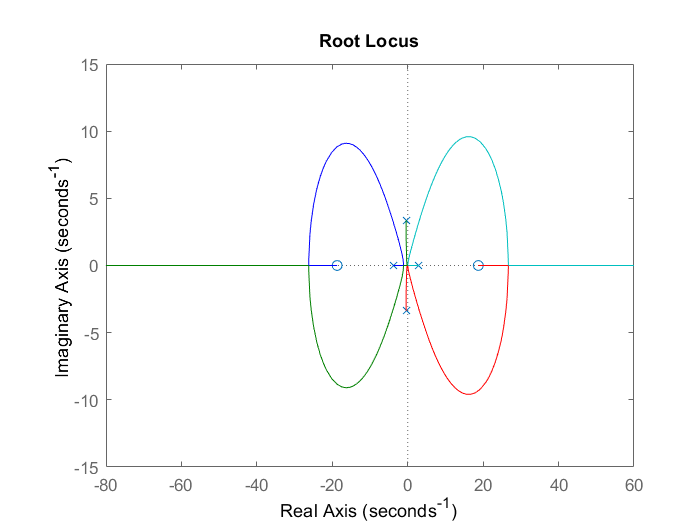

figure
% transfer function
rlocus(modified_tf_sys);

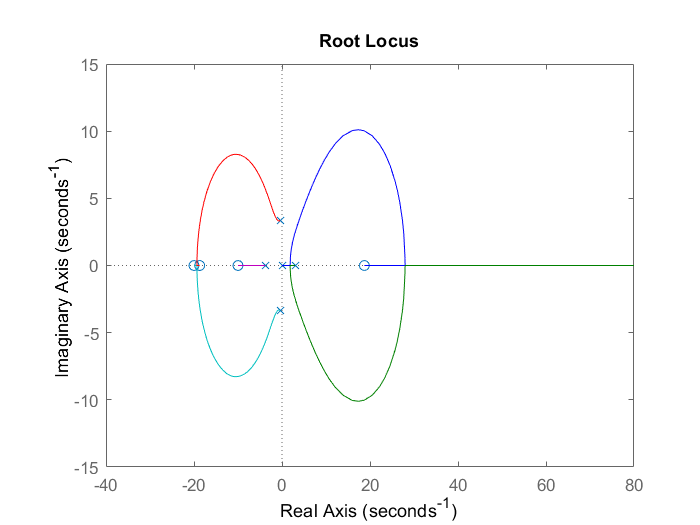


% Define PID controller gains
Kd = 1/100;
Kp = 30/100;
Ki = 200/100;


% Create PID controller transfer function
pid_tf = tf([Kd, Kp, Ki], [1, 0]);

% Combine PID controller with the plant transfer function
sys_with_pid = series(pid_tf, modified_tf_sys);
figure
% Plot root locus

rlocus(sys_with_pid);

## Q8

% new system without unstable pole
[numerator1, denominator1] = zp2tf(z1, p1(1:3), k1);
[numerator2, denominator2] = zp2tf(z2, p2(1:3), k2);
tf_modified = tf({numerator1; numerator2}, {denominator1; denominator2});
disp(tf_modified)

  2×1 tf array with properties:

       Numerator: {2×1 cell}
     Denominator: {2×1 cell}
        Variable: 's'
         IODelay: [2×1 double]
      InputDelay: 0
     OutputDelay: [2×1 double]
              Ts: 0
        TimeUnit: 'seconds'
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {2×1 cell}
      OutputUnit: {2×1 cell}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
    SamplingGrid: [1×1 struct]



[A_modified, B_modified, C_modified, D_modified] = tf2ss(cell2mat(tf_modified.Numerator), cell2mat(tf_modified(1).Denominator))

A_modified =    -4.7029  -14.8175  -44.2986
    1.0000         0         0
         0    1.0000         0


B_modified =      1
     0
     0


C_modified =    -0.0699    0.0000   24.5001
    3.4965         0    0.0000


D_modified =      0
     0


sys_modified = ss(A_modified, B_modified, C_modified, D_modified)

sys_modified =
 
  A = 
           x1      x2      x3
   x1  -4.703  -14.82   -44.3
   x2       1       0       0
   x3       0       1       0
 
  B = 
       u1
   x1   1
   x2   0
   x3   0
 
  C = 
              x1         x2         x3
   y1   -0.06993  9.938e-16       24.5
   y2      3.496          0  1.373e-16
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.



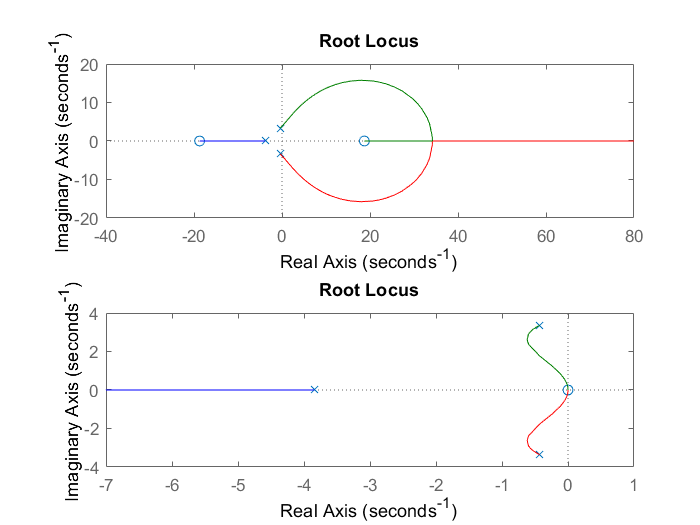

figure
for i = 1:size(B_modified, 2)
    for j = 1:size(C_modified, 1)
        sys_siso = ss(A_modified, B_modified(:,i), C_modified(j,:), D_modified(j,i));
        subplot(size(C_modified, 1), size(B_modified, 2), (j-1)*size(B_modified, 2) + i);
        rlocus(sys_siso);
    end
end

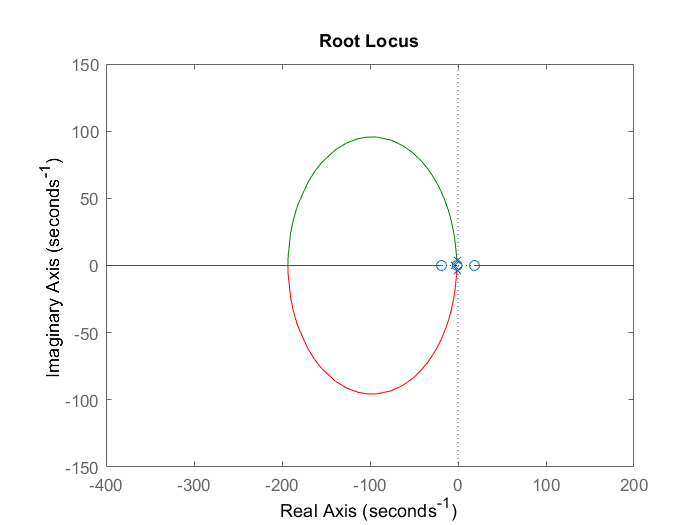

% Define PID controller gains
Kd = 1;
Kp = 1;
Ki = 0;


% Create PID controller transfer function
pid_tf = tf([Kd, Kp, Ki], [1, 0]);

% Combine PID controller with the plant transfer function
sys_with_pid = series(pid_tf, tf_modified(1));
figure
% Plot root locus

rlocus(sys_with_pid);

Co_mod = ctrb(sys_modified)

Co_mod =     1.0000   -4.7029    7.2995
         0    1.0000   -4.7029
         0         0    1.0000


fprintf('Rank(Co_mod)= %d\n', rank(Co_mod));

Rank(Co_mod)= 3



Ob_mod = obsv(sys_modified)

Ob_mod =    -0.0699    0.0000   24.5001
    3.4965         0    0.0000
    0.3289   25.5363    3.0978
  -16.4434  -51.8087 -154.8881
   23.9897   -1.7752  -14.5684
   25.5225   88.7619  728.4196


fprintf('Rank(Ob_mod)= %d\n', rank(Ob_mod));

Rank(Ob_mod)= 3


function dydt = odefcn(t, x, u)
    J_b = 4.32e-5;
    r = 0.02;
    m = 0.27;
    g = 9.81;
    J_w = 14.025e-2;
    k = 1e-3;
    l = 0.49;
    b = 1;
    A11 = J_b/r^2+m;
    A12 = (m*r^2 +J_b)/r;
    A21 =A12;
    A22 =(m*x(1)^2+J_w+J_b);
    B11 = (m*g*sin(x(3)));
    B12 = m*x(1)*x(4)^2;
    B21 =l*cos(x(3))*u;
    B22= m*g*x(1)*cos(x(3));
    B23 =k*l^2*x(3)*(-1);
    B24 =-(2*m*x(1)*x(2)+b*l^2)*x(4);
    C1= B11 +B12;
    C2 =B21 +B22 +B23 +B24;
    detA=A11*A22-A12*A21;
    dydt = zeros(4, 1);
    dydt(1) = x(2);
    dydt(2) = (A22*C1-A12*C2)/detA;
    dydt(3) = x(4);
    dydt(4) = (-A21*C1+A11*C2)/detA;
end